
clc, clearvars

# **MRI local wire simulation**

The purpose of wire_function() is to simulate the path of a local wire through the body in the electric field.  

## **Required Inputs**

eField (as a file name):

"simulatedBodyCoilEfield (1).mat"

ans = "simulatedBodyCoilEfield (1).mat"

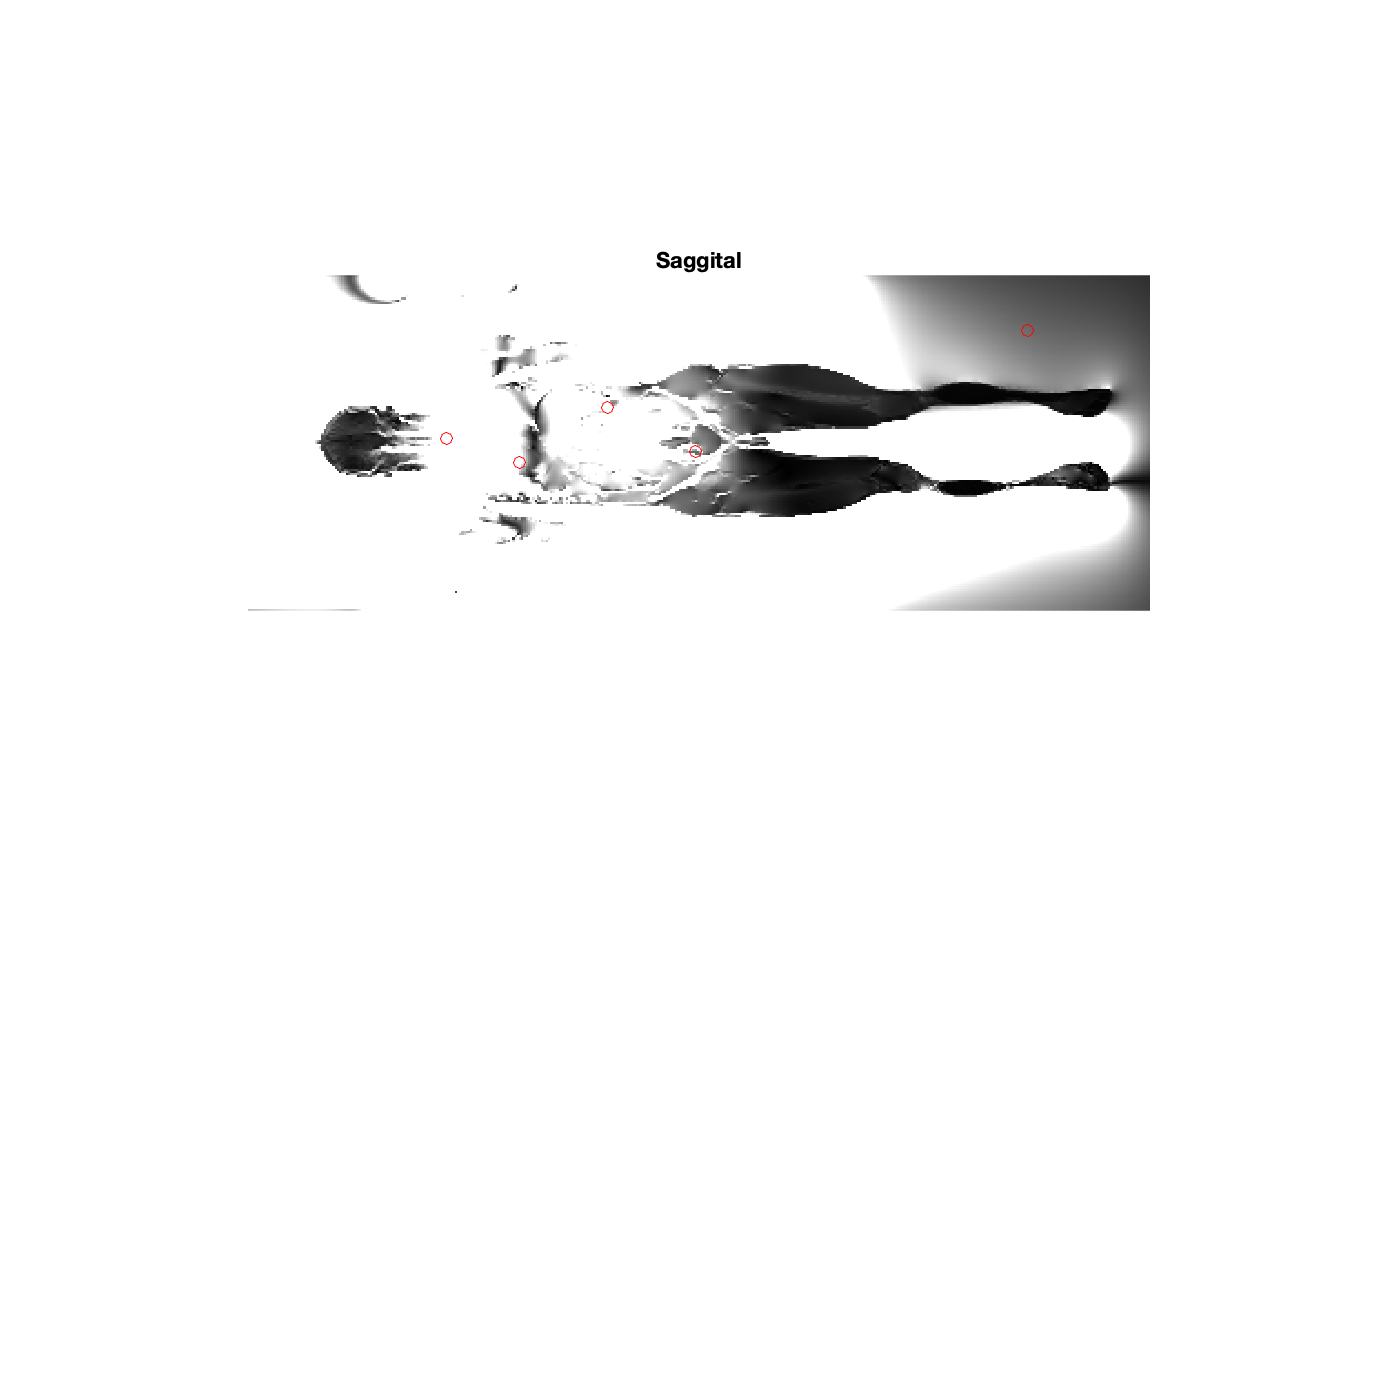

s = load(ans);
title('Saggital')

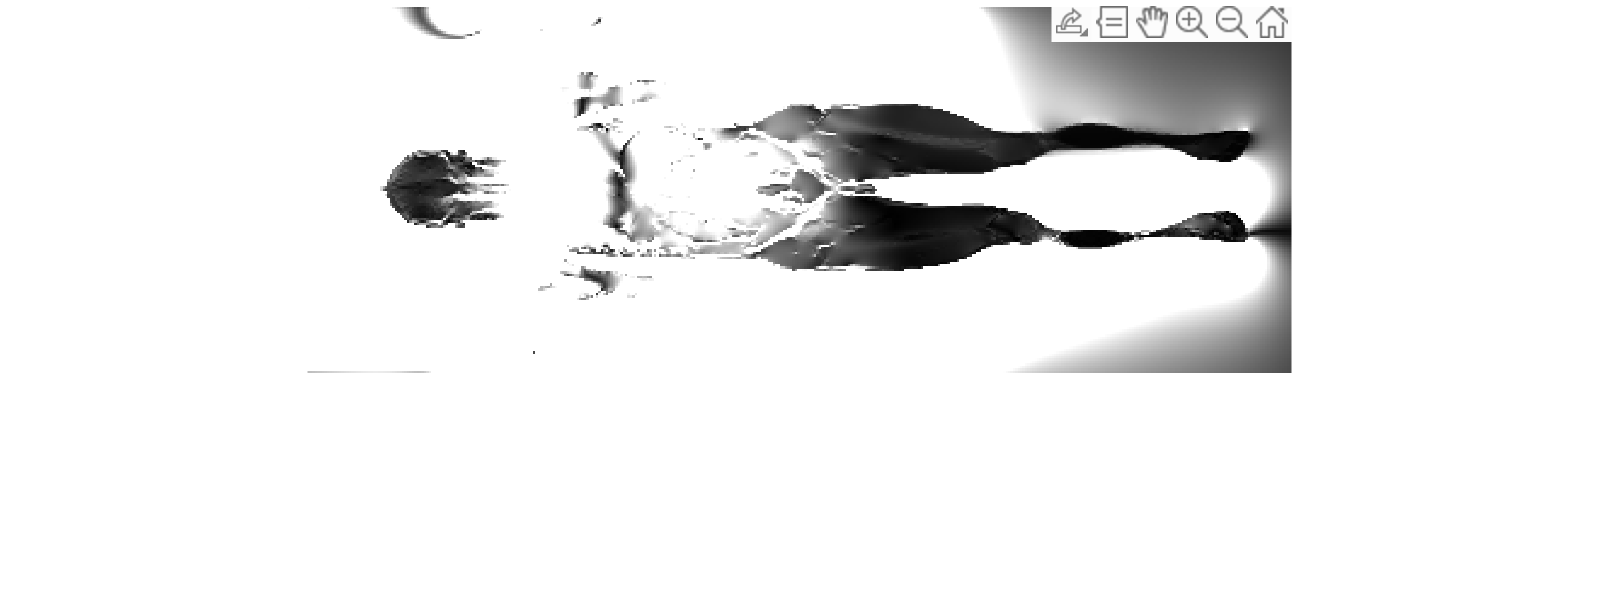

z =    98.7077
  124.2869
  190.2978
  363.5765


x =    70.0178
   83.2199
   73.3183
   27.9358


imshow(squeeze(abs(s.E(:,75,:,1))))
set(gcf,'Position',[300 300 800 300])
[z, x] = getpts

Pick your points for the y direction on the green lines. 

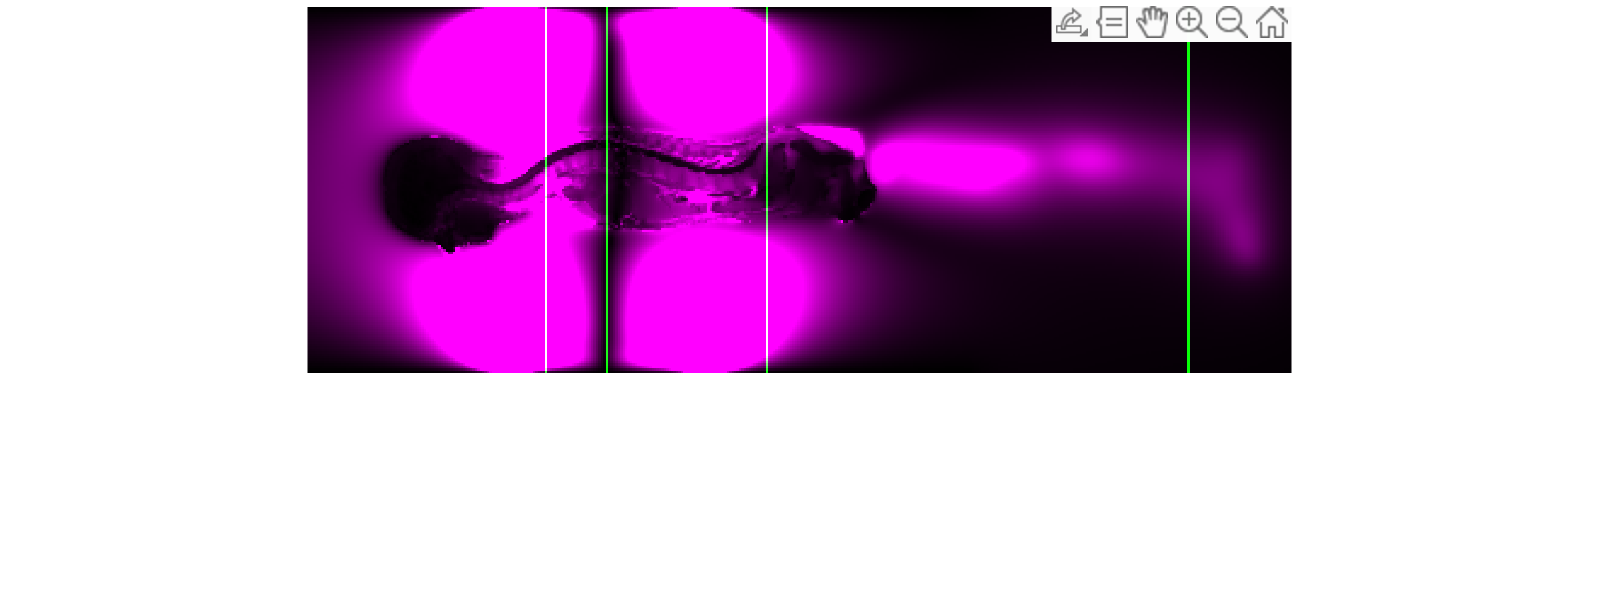


vol = zeros(length(s.axis1)-1, length(s.axis2)-1);
vol(:,round(z)) = 1;

s.E(abs(s.E) > 5) = 5;
imshow(imfuse(vol, squeeze(abs(s.E(75,:,:,1)) ), 'Scaling', 'independent')) 
set(gcf,'Position',[300 300 800 300])
[zc, y] = getpts;

p = [x, y, z];
points = convert_points(p, s, 'version', "v1")

output =      1     1     1
     1     1     1
     1     1     1
     1     1     1


points =    -0.0317   -0.0417   -0.1292
    0.0333    0.0133   -0.0042
   -0.0167   -0.0517    0.3258
   -0.2417   -0.2517    1.1958


num_points = size(points, 1);     

Pick the minimum and maximum values for each of your points. 

1) Select a value above and below for the x direction.

2) Select a value to the right and left when choosing z ranges. 

3) Select a value above and below for the y direction. 

Coordinates that you do not specify as changing later on will not be used. **Pick maximum first and minimum second for each point. **

y ranges:

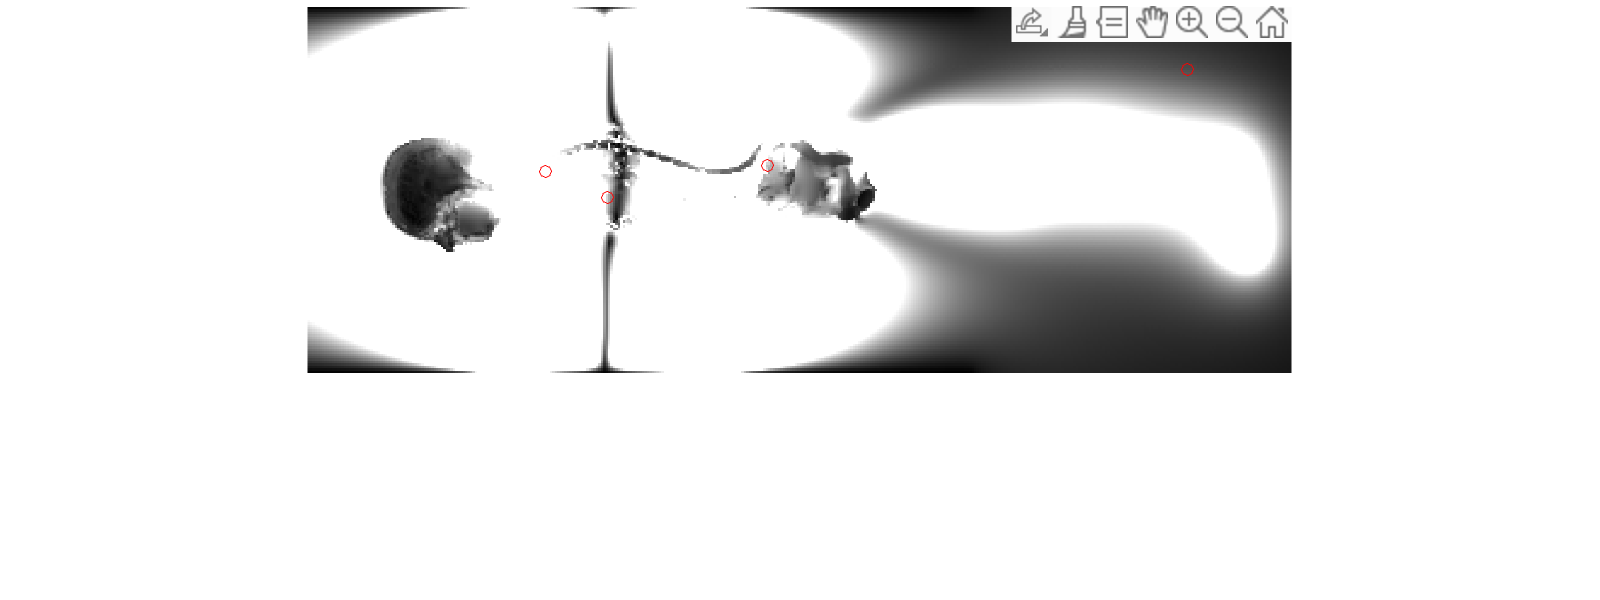

zn =   102.0082
  102.0082
  121.8115
  124.2869
  193.5984
  188.6475
  363.5765
  363.5765


y_ranges =    64.2418
   80.7445
   63.4167
   90.6462
   60.9413
   86.5205
   19.6844
   36.1872


%voll = zeros(length(s.axis1)-1, length(s.axis2)-1);
%voll(round(points()),round(points(:, 1:2))) = 1; %how to only do points?
imshow(squeeze(abs(s.E(75,:,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, y, 'ro');
hold off
[zn, y_ranges] = getpts

y_ranges = reshape(y_ranges, 2, num_points)' %check if order is correct

y_ranges =    64.2418   80.7445
   63.4167   90.6462
   60.9413   86.5205
   19.6844   36.1872


y_ranges = convert_points(y_ranges, s, 'version', "v2", 'yd', "T")

y_ranges =    -0.0617    0.0233
   -0.0667    0.0733
   -0.0767    0.0533
   -0.2817   -0.2017


z ranges:

z_ranges =    83.8552
  107.7842
  108.6093
  137.4891
  172.1448
  210.1011
  347.8989
  374.3033


yn =    70.0178
   70.0178
   81.5697
   81.5697
   69.1926
   69.1926
   28.7609
   28.7609


%same plot
imshow(squeeze(abs(s.E(75,:,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, y, 'ro');
hold off
[z_ranges, yn] = getpts

z_ranges = reshape(z_ranges, 2, num_points)'%convert points

z_ranges =    83.8552  107.7842
  108.6093  137.4891
  172.1448  210.1011
  347.8989  374.3033


z_ranges = convert_points(z_ranges, s, 'version', "v2", 'zd', "T")

z_ranges =    -0.2042   -0.0842
   -0.0792    0.0608
    0.2358    0.4258
    1.1158    1.2458


x ranges:

imshow(squeeze(abs(s.E(:,75,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, x, 'ro');
hold off
[zn, x_ranges] = getpts

zn =    99.5328
   99.5328
  123.4617
  123.4617
  189.4727
  189.4727
  366.0519
  366.0519


x_ranges =    60.9413
   79.0943
   66.7172
   96.4221
   65.0669
   88.9959
   22.9850
   40.3128


x_ranges = reshape(x_ranges, 2, num_points)'

x_ranges =    60.9413   79.0943
   66.7172   96.4221
   65.0669   88.9959
   22.9850   40.3128


%x_ranges = reshape(x_ranges, 2, [])'
x_ranges = convert_points(x_ranges, s, 'version', "v2", 'xd', "T")

x_ranges =    -0.0767    0.0133
   -0.0467    0.0983
   -0.0567    0.0633
   -0.2667   -0.1817


ranges = [x_ranges y_ranges z_ranges];

which points will be changing (give a list of their indices): 

[1 2 3]

ans =      1     2     3


check of all of the points that are changing:

changing = ans;

## **Optional Inputs**

Drag to choose how long you want your wire to be. Your points will be adjusted to this length. Units are in meters. 

1

ans = 1

nom_length = ans;

Do you want a plot of the wire to be displayed?

"Yes"

ans = "Yes"

if ans == "Yes"
    show_plot = true;
else
    show_plot = false;
end

Do you want a histogram of the lengths of the trajectories for the wire (modified and unmodified) to be displayed?

"Yes"

ans = "Yes"

if ans == 'Yes'
    show_graph = true;
else
    show_graph = false;
end

What is the indice of the point on the wire that intersects with the body?

3

ans = 3

intersecting = ans;

Drag to pick the number of steps between ranges. For example, if there is a range [-1 2] and num_steps is 3, the function will use 3 values in between -1  and 2. Default value: 5. num_steps^3 is the number of trajectories that will be calculated. 

5

ans = 5

num_steps = ans;
set(gcf,'Position',[300 300 700 700]) %weird transition

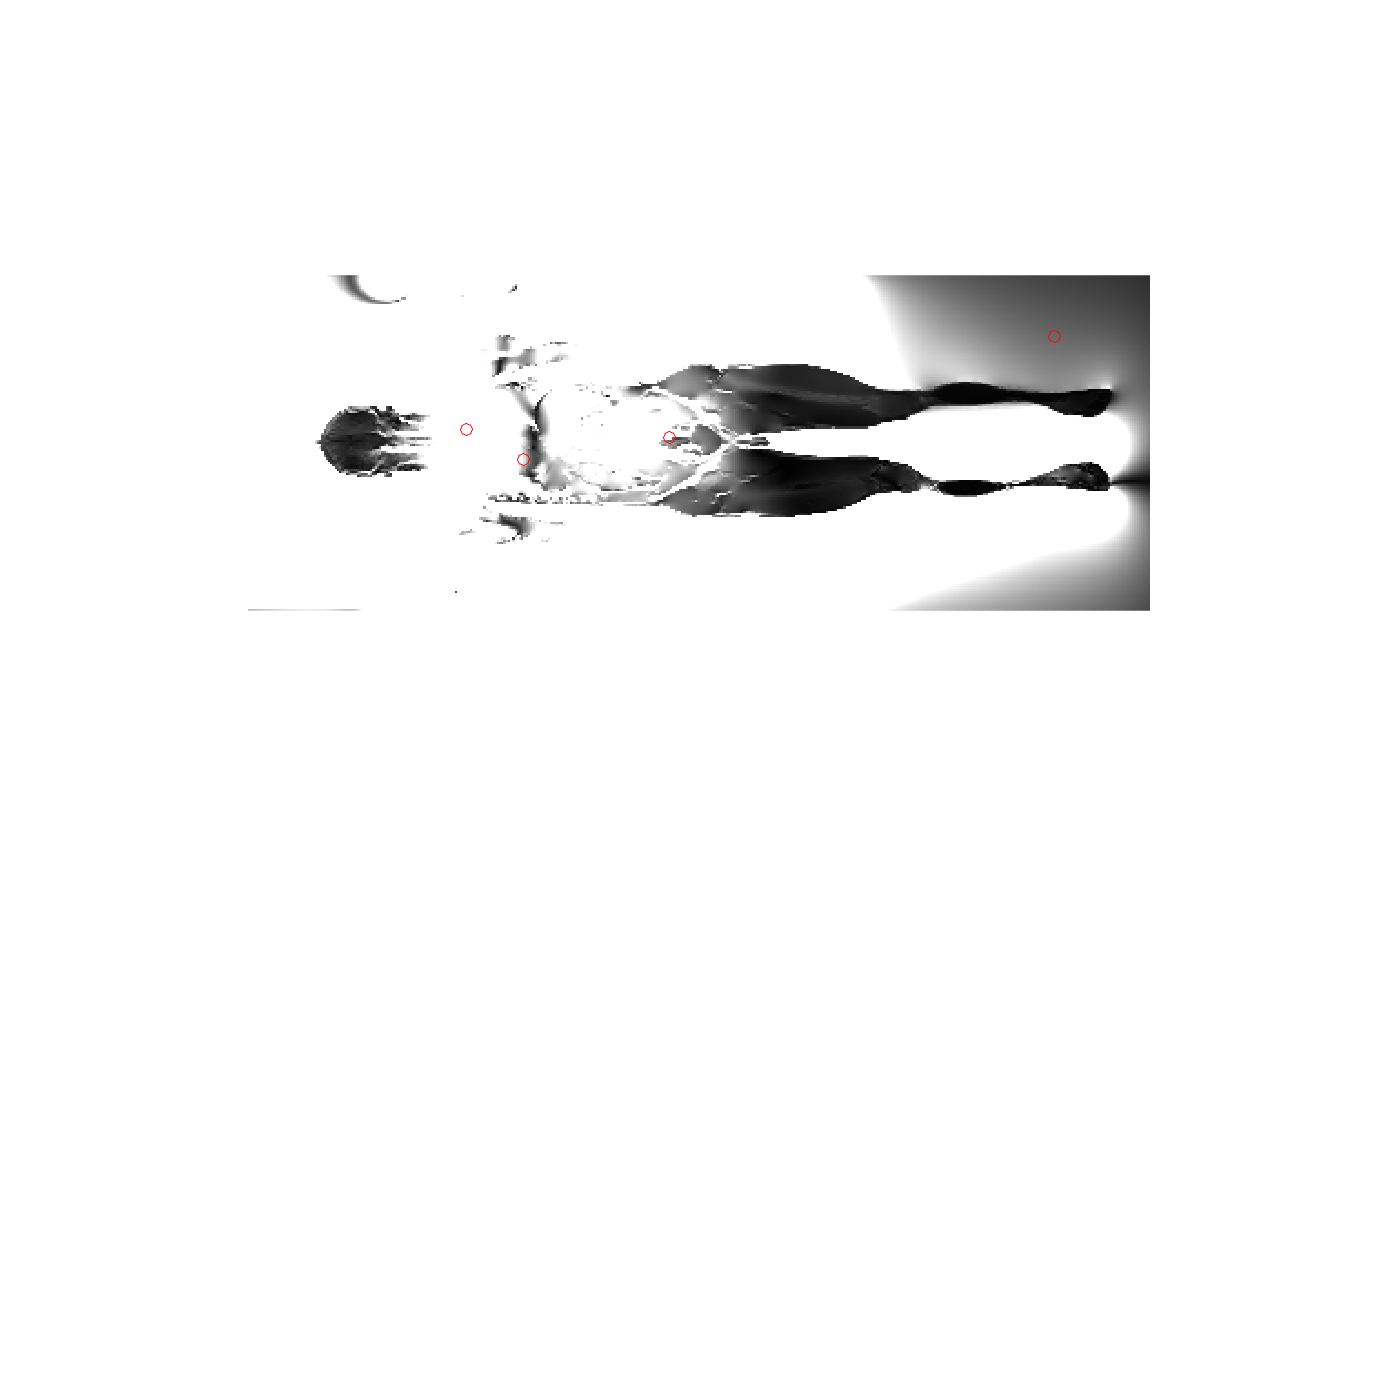

show_electric = logical
   1


length of rounded wire 1.01

length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01l

length of rounded wire 1.00

length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.01length of rounded wire 1.02length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.01length of rounded wire 1.02length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.02length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.03length of rounded wire 1.02length of rounded wire 1.01l

length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00l

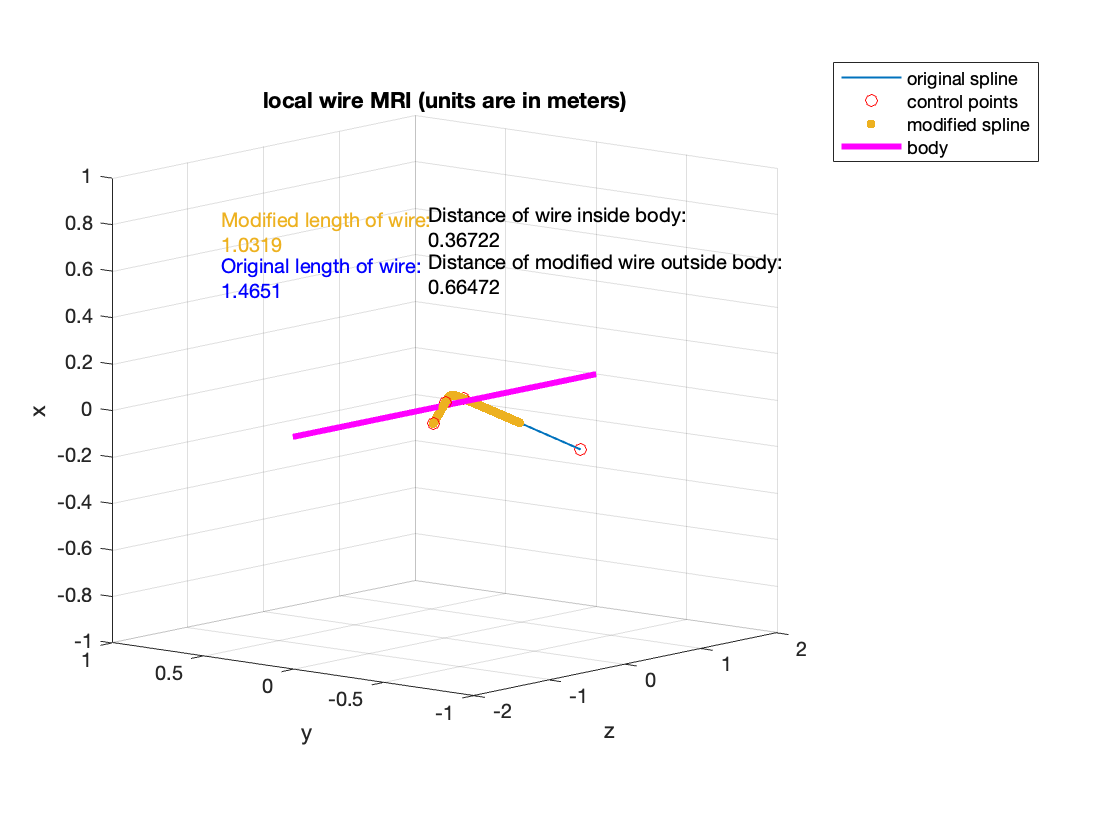

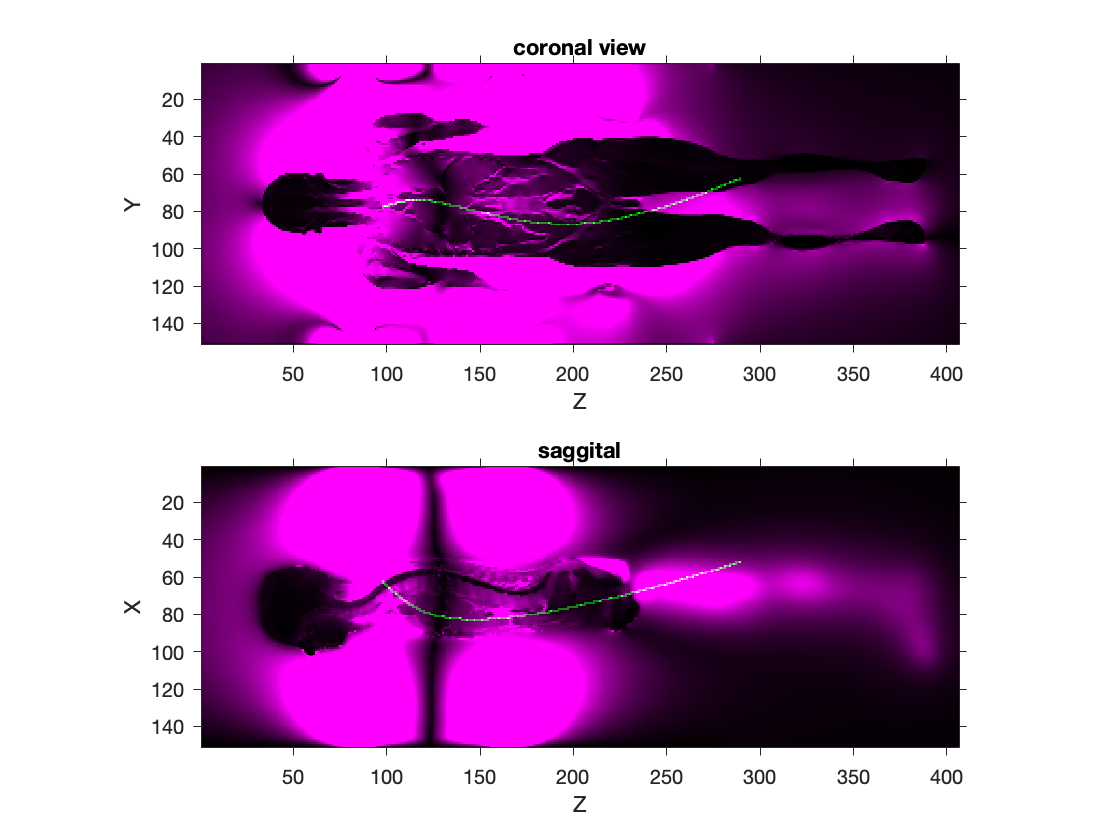

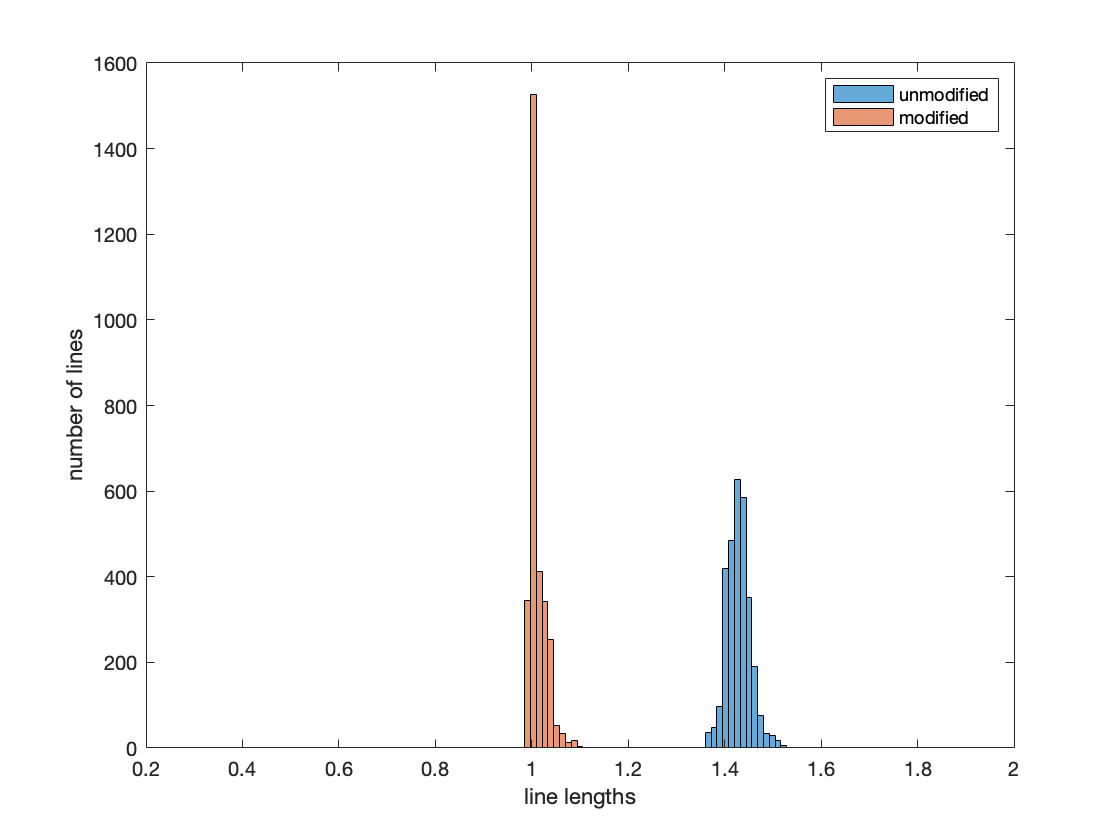

[output, wire_lengths, output3] = wire_function_v8(...
    points',...
    ranges,...
    changing,...
    s,...
    'nom_length', nom_length,...
    'show_plot', show_plot,...
    'show_graph', show_graph,...
    'intersecting_index', intersecting,...
    'num_steps', 10,... %changed from num_steps
    'give_warnings', false, ... 
    'direction', "Right");